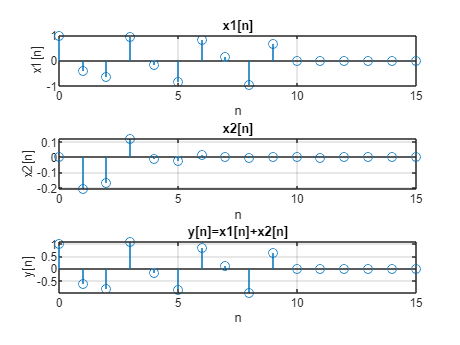

% 1)
clc, clear, close all;

U = @(n) 1.*(n>=0);
x1 = @(n) cos(2*n).*(U(n) - U(n-10));
x2 = @(n) 2.^(-n).*cos(2*n).*(U(n-1) - U(n-12));
n = 0:15;
y = Signal_Sum(x1(n), x2(n));

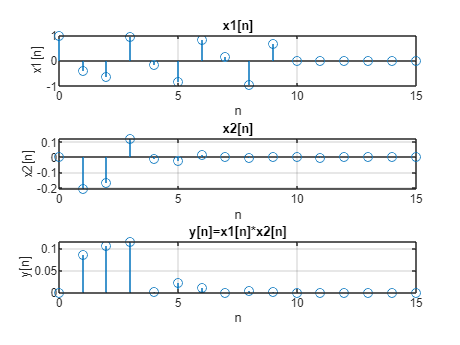

% 2)
clc, clear, close all;

U = @(n) 1.*(n>=0);
x1 = @(n) cos(2*n).*(U(n) - U(n-10));
x2 = @(n) 2.^(-n).*cos(2*n).*(U(n-1) - U(n-12));
n = 0:15;

y = Signal_Mult(x1(n), x2(n));

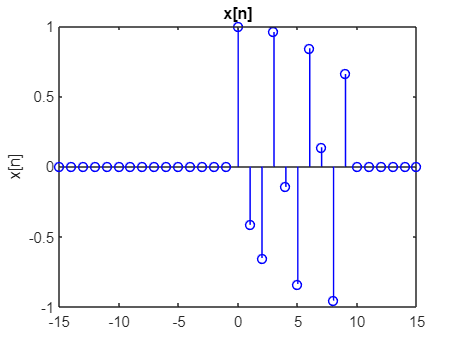

% 3)
clc, clear, close all;

n=-15:15;
x=cos(2.*n).*(1.*(n>=0)-1.*(n>=10));
stem(n,x,'b','LineWidth',1); title('x[n]');
ylabel('x[n]')

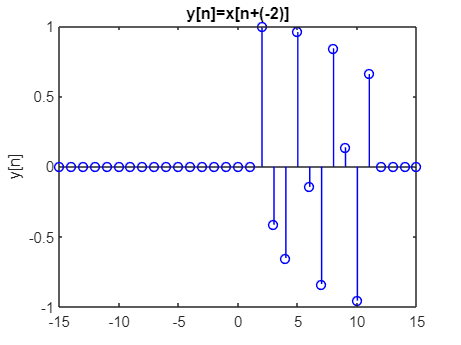

T1 = 2;
y1=Signal_Shift(x,T1);

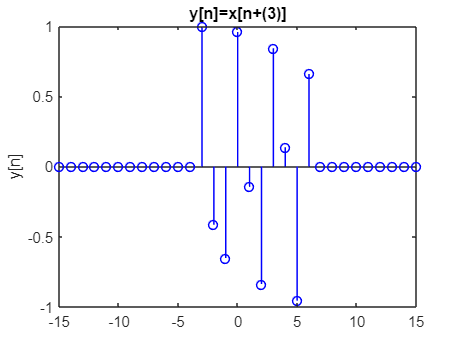

T2 = -3; 
y2=Signal_Shift(x,T2);

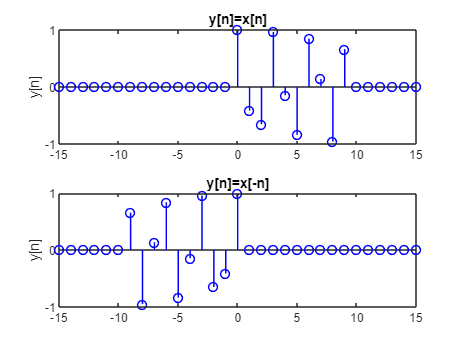

% 4)
clc, clear, close all;

n = -15:15;
U = @(n) 1.*(n>=0);
x = cos(2.*n).*(1.*U(n)-1.*U(n-10));
y = Signal_Flip(x);

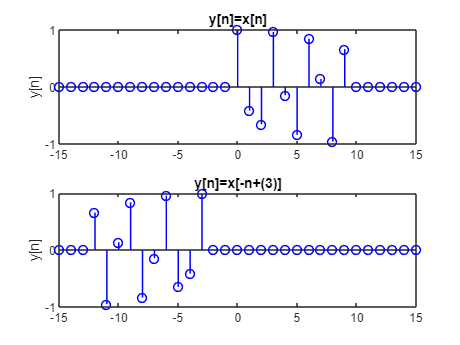

% 5)
clc, clear, close all;

n = -15:15;
U = @(n) 1.*(n>=0);
x = cos(2.*n).*(1.*U(n)-1.*U(n-10));
T = -3;
y = Signal_Flip_Shift(x,T);

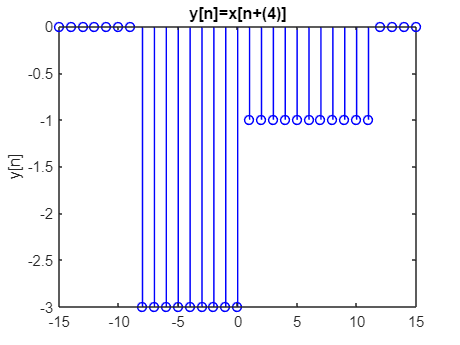

% 6)
clc, clear, close all;
n = -15:15;
U = @(n) 1.*(n>=0);
x = 2.*U(n-5)-3.*U(n+4);
y1 = 2*Signal_Shift(x, 5) - 3*Signal_Shift(x, -4);

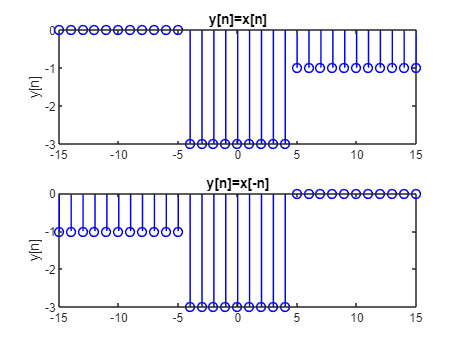

y2 = 1*Signal_Shift(x, 1) - 1*Signal_Flip(x);

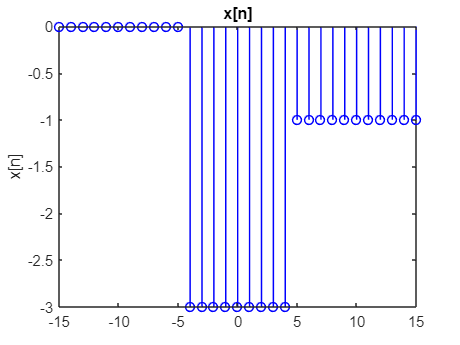

figure; stem(n,x,'b','LineWidth',1);
title("x[n]"); ylabel('x[n]')

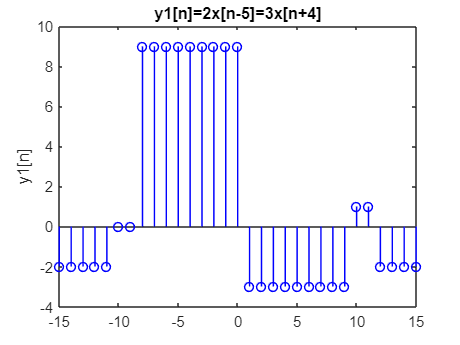

figure; stem(n,y1,'b','LineWidth',1);
title("y1[n]=2x[n-5]=3x[n+4]"); ylabel('y1[n]') 

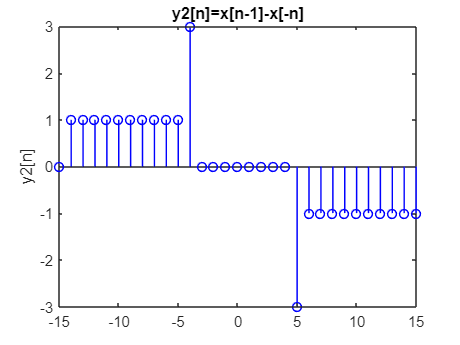

figure; stem(n,y2,'b','LineWidth',1);
title("y2[n]=x[n-1]-x[-n]"); ylabel('y2[n]')

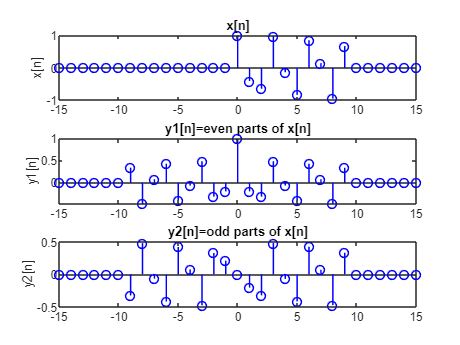

% 7)
clc, clear, close all;

n = -15:15;
U = @(n) 1.*(n>=0);
x = cos(2.*n).*(1.*U(n)-1.*U(n-10));
Signal_EvenOdd(x);

function y = Signal_Sum(X1,X2)
    X1 = X1(:);
    X2 = X2(:);
    Len1 = length(X1);
    Len2 = length(X2);
    Len = max(Len1, Len2);

    if Len1>Len2
        X2 = [X2;zeroes(Len1-Len2, 1)];
    elseif Len1<Len2
        X1 = [X1;zeroes(Len2-Len1, 1)];
    end
    y = X1+X2;
    n = 0:Len-1;
    figure; 
    subplot(311); stem(n, X1); grid; title('x1[n]'); xlabel('n'); ylabel('x1[n]');
    subplot(312); stem(n, X2); grid; title('x2[n]'); xlabel('n'); ylabel('x2[n]');
    subplot(313); stem(n, y); grid; title('y[n]=x1[n]+x2[n]'); xlabel('n'); ylabel('y[n]');
    
end


function y = Signal_Mult(X1,X2)
    X1 = X1(:);
    X2 = X2(:);
    Len1 = length(X1);
    Len2 = length(X2);
    Len = max(Len1, Len2);

    if Len1>Len2
        X2 = [X2;zeroes(Len1-Len2, 1)];
    elseif Len1<Len2
        X1 = [X1;zeroes(Len2-Len1, 1)];
    end
    y = X1.*X2;
    n = 0:Len-1;
    figure; 
    subplot(311); stem(n, X1); grid; title('x1[n]'); xlabel('n'); ylabel('x1[n]');
    subplot(312); stem(n, X2); grid; title('x2[n]'); xlabel('n'); ylabel('x2[n]');
    subplot(313); stem(n, y); grid; title('y[n]=x1[n]*x2[n]'); xlabel('n'); ylabel('y[n]');
    
end

function y = Signal_Shift(x,T)
    y=circshift(x',T);
    y=y';
    n = -15:15;

    stem(n,y,'b','LineWidth',1); title("y[n]=x[n+(" + -T + ")]");
    ylabel('y[n]')
end

function y = Signal_Flip(x)
    y = flip(x);
    n = -15:15;

    subplot(211); stem(n,x,'b','LineWidth',1);
    title("y[n]=x[n]"); ylabel('y[n]')
    subplot(212); stem(n,y,'b','LineWidth',1);
    title("y[n]=x[-n]"); ylabel('y[n]')
end

function y = Signal_Flip_Shift(x, T)
    n = -15:15;
    y = flip(x);
    y = circshift(y',T);
    subplot(211); stem(n,x,'b','LineWidth',1);
    title("x[n]"); ylabel('x[n]')
    subplot(212); stem(n,y,'b','LineWidth',1);
    title("y[n]=x[-n+(" + -T + ")]"); ylabel('y[n]')
end

function Signal_EvenOdd(x)
    n = -15:15;
    even = (x + Signal_Flip(x))/2;
    odd = (x - Signal_Flip(x))/2;
    subplot(311); stem(n,x,'b','LineWidth',1);
    title("x[n]"); ylabel('x[n]')
    subplot(312); stem(n,even,'b','LineWidth',1);
    title("y1[n]=even parts of x[n]"); ylabel('y1[n]')
    subplot(313); stem(n,odd,'b','LineWidth',1);
    title("y2[n]=odd parts of x[n]"); ylabel('y2[n]')
end